clear;clc;close
load DelMar_data.mat

uu = [u;v];
uu = uu';
uu(isnan(uu))=0;

[U,S,V] = svd(uu);
dS = diag(S);
pvar = dS.^2/sum(dS.^2)*100;
A = U*S; % temporal expansion
%%

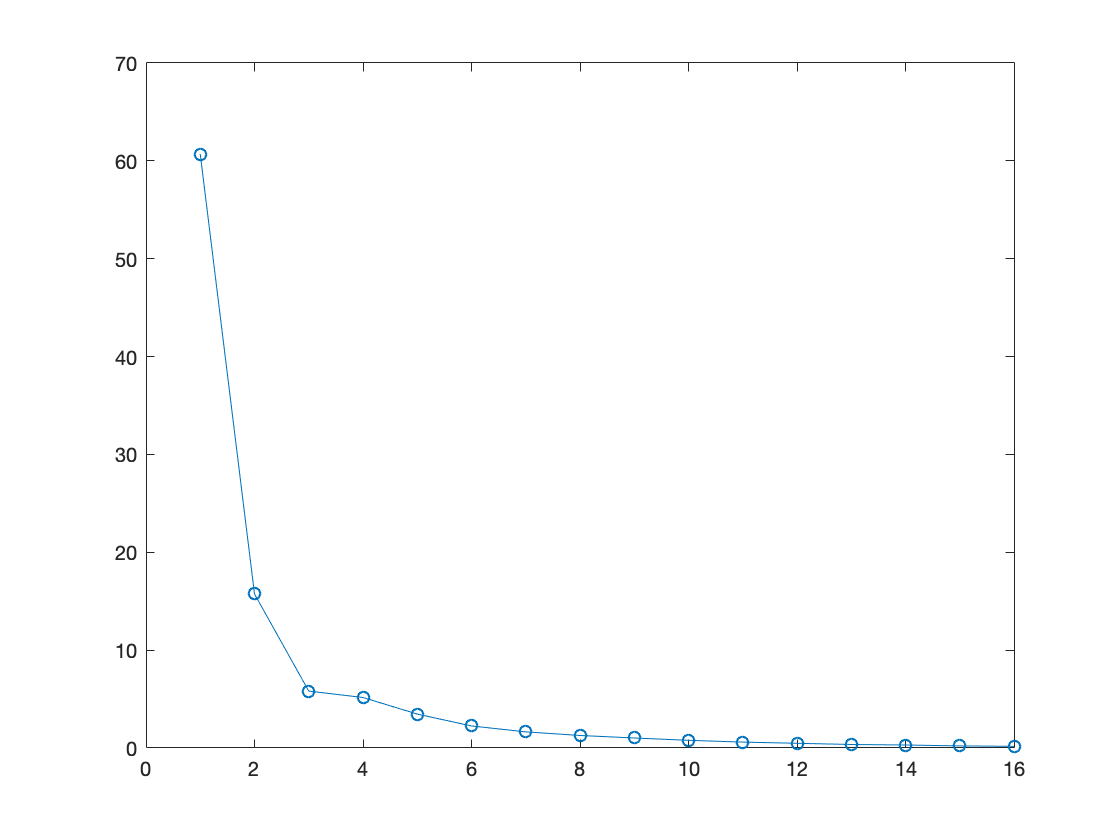

% Pc first mode
% plot(t,U(:,1))
figure(1)
clf
plot(pvar,'o-')

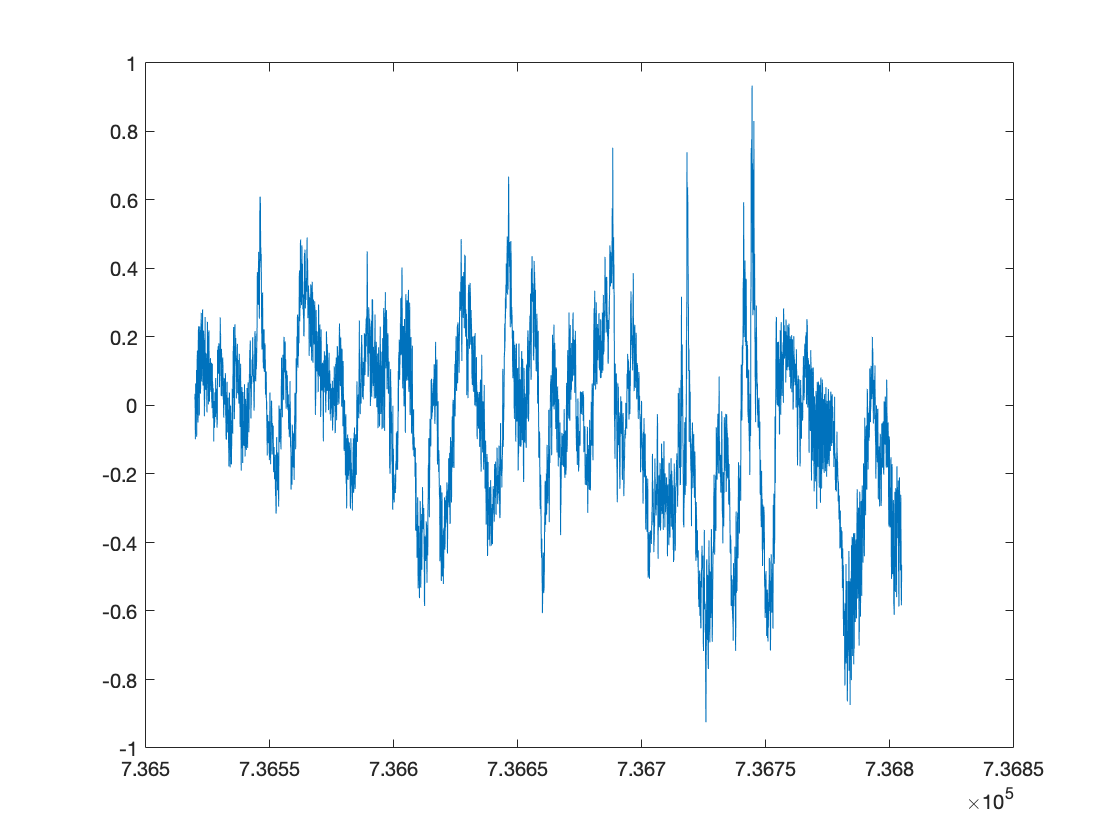

figure(2)
clf
plot(t,A(:,1))

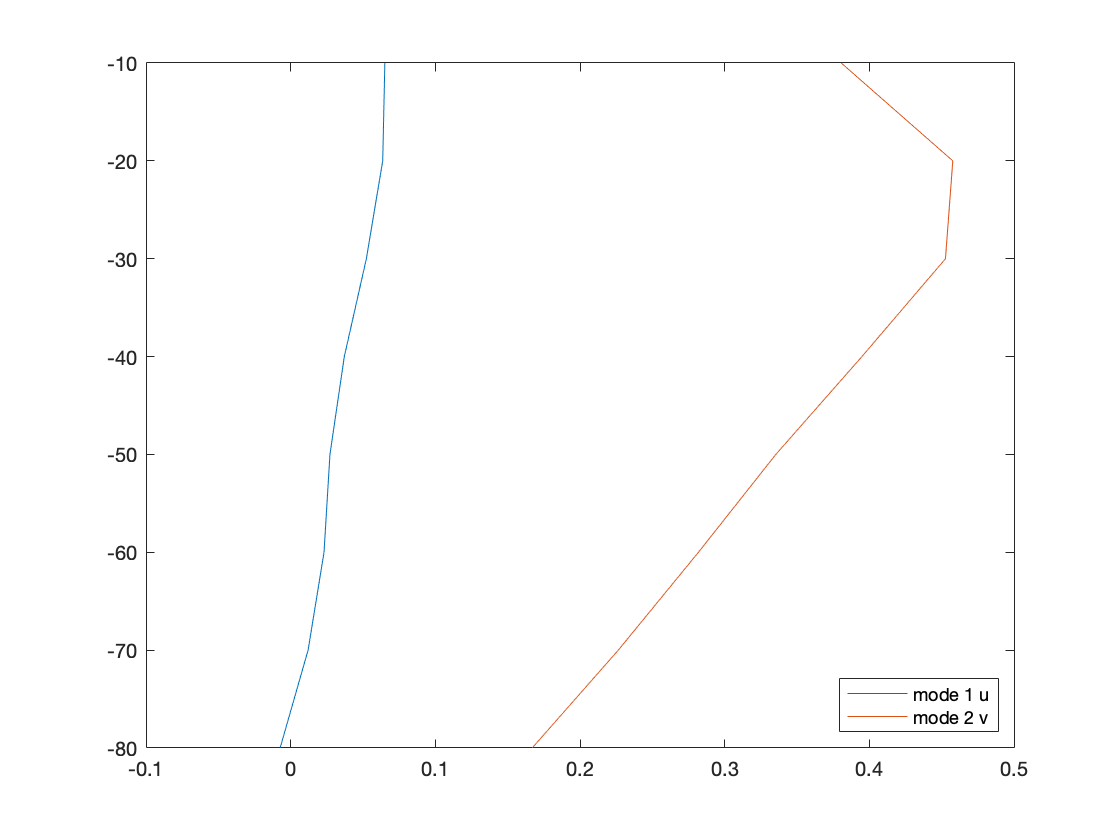

figure(3)
clf
plot(V(1:8,1),z,V(9:16,1),z) % first 1-8 is u 9-16 is v
legend({'mode 1 u','mode 1 v'},'Location','SE')

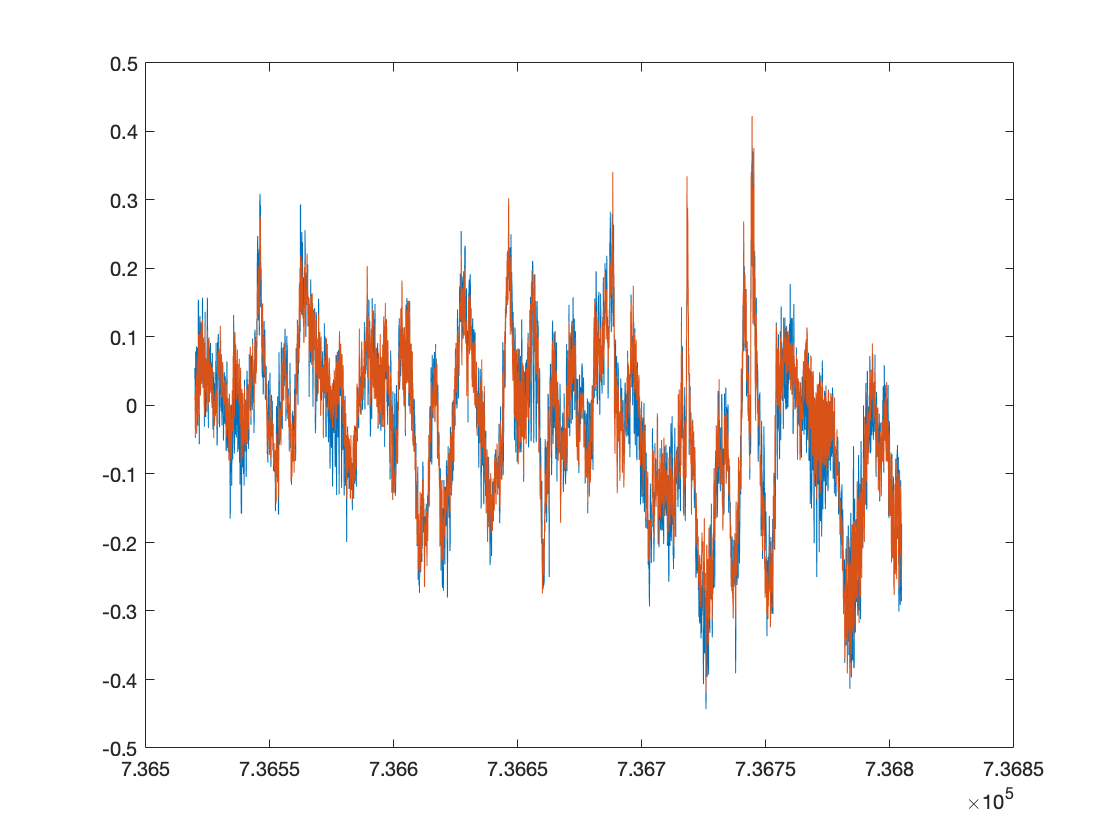

figure(4)
plot(t,v(3,:),t,A(:,1)*V(11,1)) % multiply svd by original A

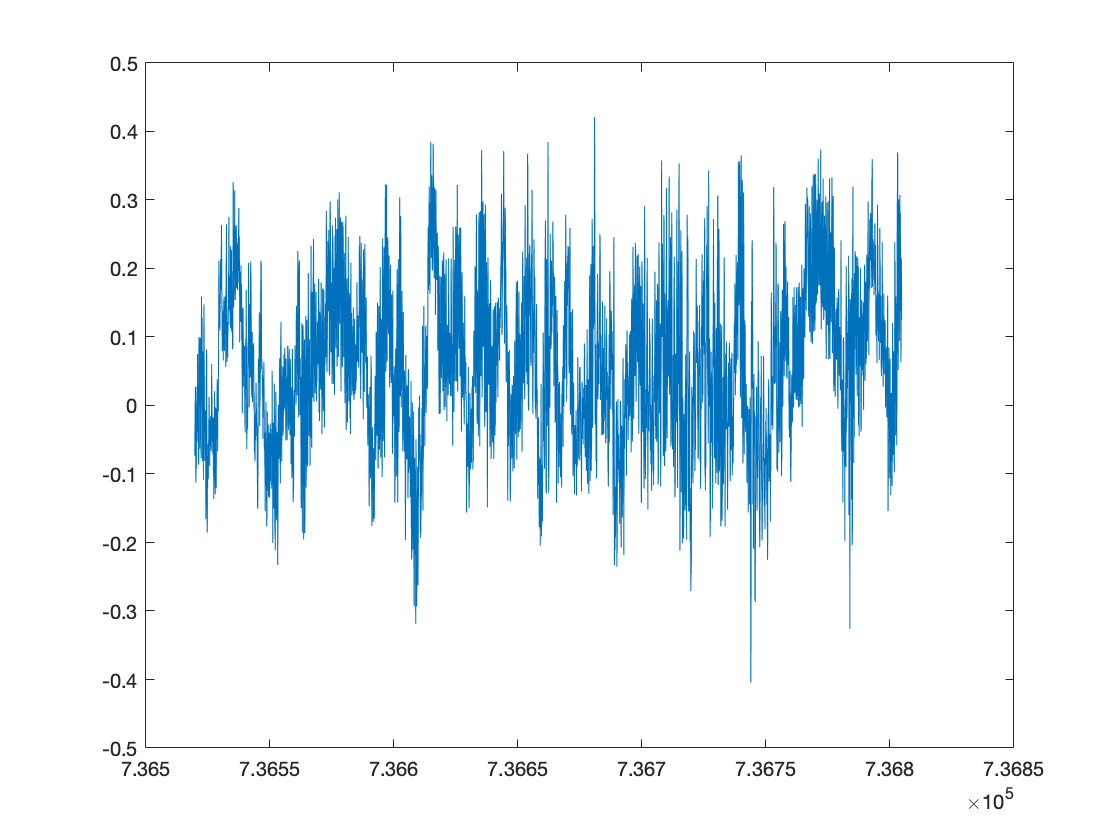

% V(11 is the 3rd mode of the v data)

figure(5) % mode 2
plot(t,(A(:,2))) %mode 2 

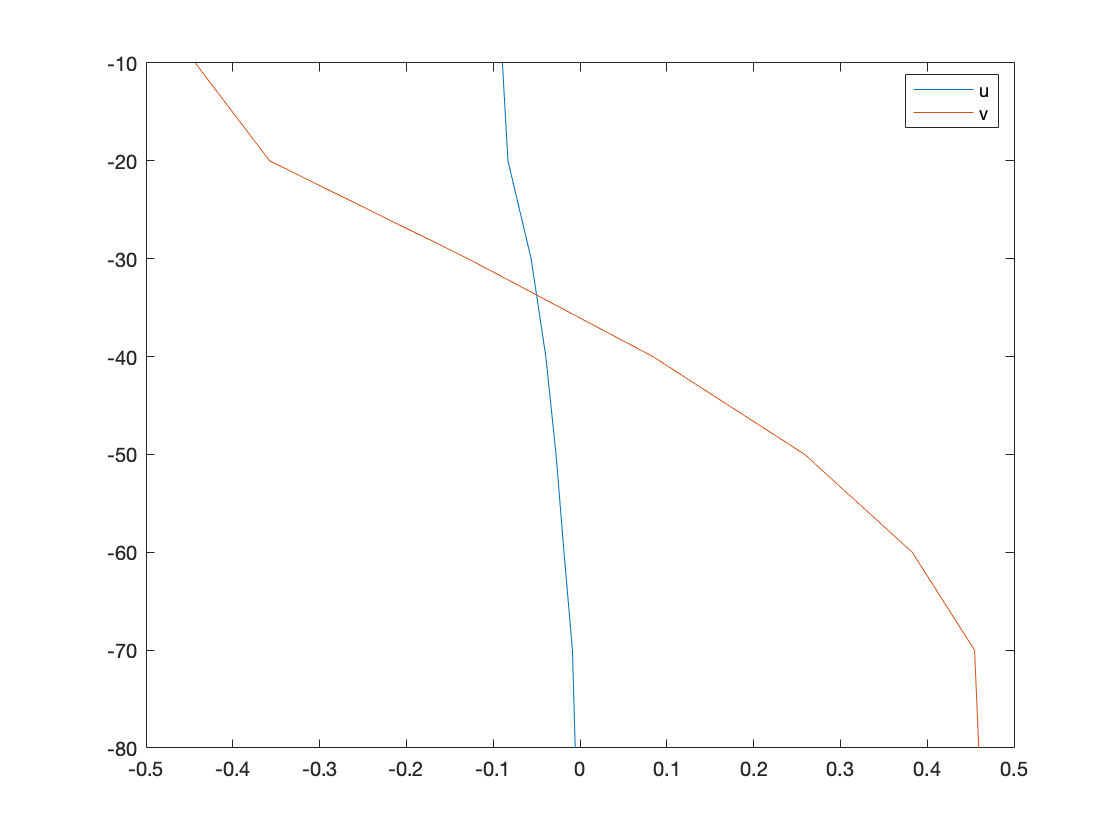

plot(V(1:8,2),z,V(9:16,2),z)
legend({'u (E-W)','v (N-S)'},'location','best')

% x axis is speed, y is depth
% upper level flow dominated by 

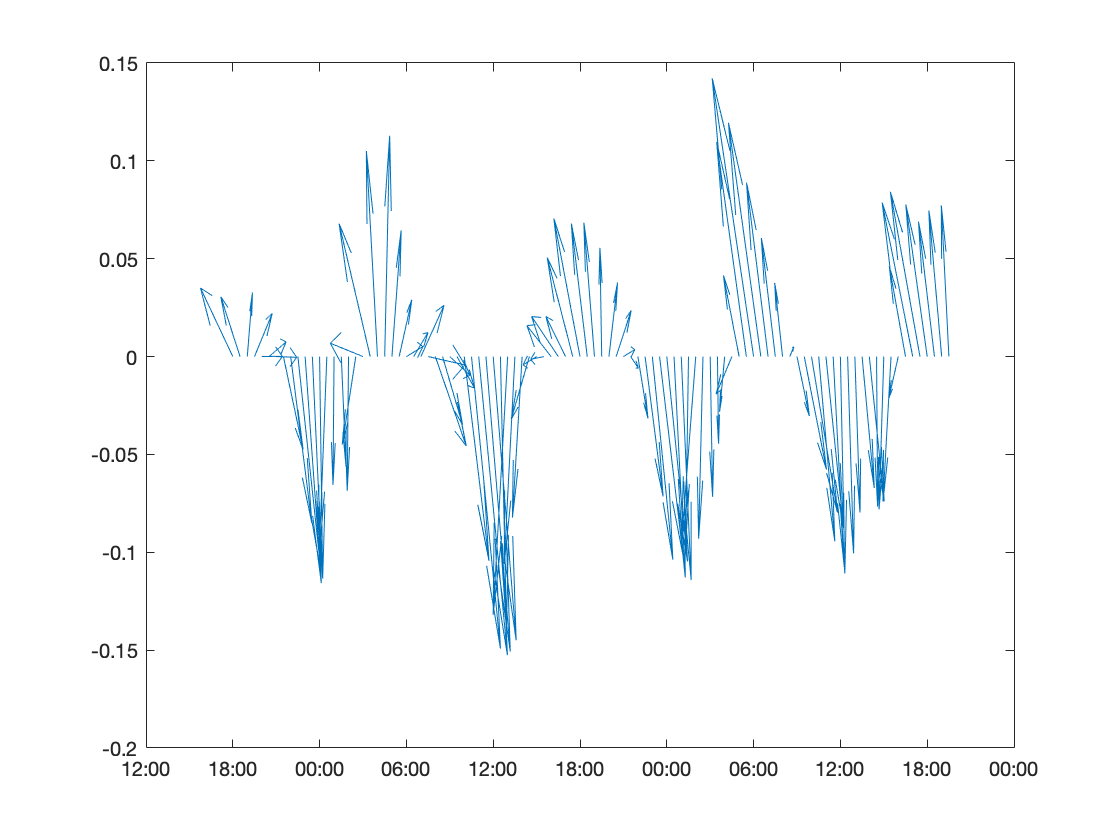

% quiver
figure(6)
clf;
quiver(t(1:100),zeros(1,100),u(1,1:100),v(1,1:100))
datetick

## what is u(1,:) vs u(2,:)

% horizontal components of velocity at depth?
quiver3(t,z,1,u(:,:),z,v(1,:));hold on

Error using quiver3 (line 44)
Z and U must be the same size.

quiver3(t,z,t,u(1,:),1,v(1,:))

Error using quiver3 (line 44)
U and V must be the same size.

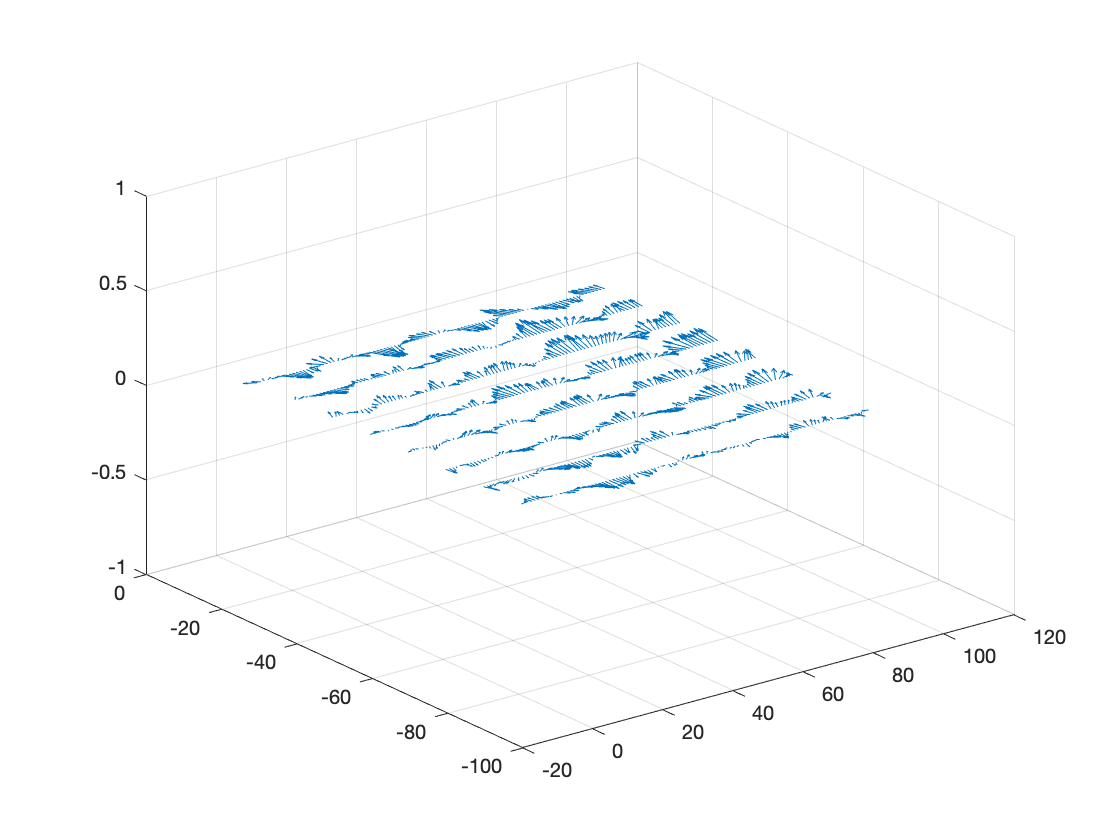

len=100;
quiver3(1:len,z,zeros(length(z),len),u(:,1:len),v(:,1:len),zeros(length(z),len)) %working (flat)

quiver3(1:len,zeros(length(z),len),z,u(:,1:len),v(:,1:len),len,zeros(length(z))) %working (flat)

Error using quiver3 (line 44)
AutoScaleFactor must be a scalar double.

% quiver3(100,8,zeros(8,100),